# Sequence of Frames Classification Using LSTM

This example shows how to create a network for video classification by combining a pretrained image classification model and an LSTM network.

To create a deep learning network for video classification:

- Convert videos to sequences of feature vectors using a pretrained convolutional neural network, such as GoogLeNet, to extract features from each frame.

- Train an LSTM network on the sequences of frame to predict the labels.

In the next module, we can assemble a network that classifies videos directly by combining layers from both networks.

% Clear workspace and command window
clear;
clc;

## HMBD51 dataset

The HMBD51 data set from [HMDB: a large human motion database](http://serre-lab.clps.brown.edu/resource/hmdb-a-large-human-motion-database/) [1] contains 6849 clips divided into 51 action categories, each containing a minimum of 101 clips. The videos are collected from various sources, mostly from movies, and a small proportion from public databases such as the Prelinger archive, YouTube and Google videos. The actions categories can be grouped in five types:

- General facial actions smile, laugh, chew, talk.

- Facial actions with object manipulation: smoke, eat, drink.

- General body movements: cartwheel, clap hands, climb, climb stairs, dive, fall on the floor, backhand flip, handstand, jump, pull up, push up, run, sit down, sit up, somersault, stand up, turn, walk, wave.

- Body movements with object interaction: brush hair, catch, draw sword, dribble, golf, hit something, kick ball, pick, pour, push something, ride bike, ride horse, shoot ball, shoot bow, shoot gun, swing baseball bat, sword exercise, throw.

- Body movements for human interaction: fencing, hug, kick someone, kiss, punch, shake hands, sword fight.

### Download Data

Download the HMBD51 data set from [HMDB: a large human motion database](http://serre-lab.clps.brown.edu/resource/hmdb-a-large-human-motion-database/) and extract the RAR file into a folder named `hmdb51_org. `The` downloadHMBD51` script automatically downlad the RAR archive from the website. 

**Since the dataset takes time to download you can choose to not download it (downloadDS=false) and use a small version of this dataset in the following sections. In this way, the network will not have good performance. Anyway, you can use the pre-trained weights given.**

downloadDS = false;

if downloadDS
    downloadHMBD51; % download the dataset from the authors website
                    % unrar the files in datafolder 
    
    dataFolder = "hmdb51_org";
else 
    dataFolder = "hmdb51_small";
    unzip('hmdb51_small.zip');
end

Please, **extract the RAR file by yourself** before running this section.

Then use the supporting function `hmdb51Files` to get the file names and the labels of the videos.

[files,labels] = hmdb51Files(dataFolder);

### Visualize the Videos

Read the videos of various classes using the `readVideo` helper function, defined at the end of this example, and view the size of the video. The video is a *H*-by-*W*-by-*C*-by-*S* array, where *H*, *W*, *C*, and *S* are the height, width, number of channels, and number of frames of the video, respectively.

type = "draw_sword";
n = sum(labels==type);
fprintf("There are %d video(s) of %s in the HMDB51 dataset\n",(sum(labels==type)),type);
idx = 1;
filenames = files(labels==type);
video = readVideo(filenames(idx));
fprintf("The size of the video is: %d x %d x %d for each of the %d frame(s)",size(video));

To view the video, use the `implay` function (requires Image Processing Toolbox™). This function expects data in the range [0,1], so we first divide the data by 255. Alternatively, you can loop over the individual frames and use the `imshow` function.

numFrames = size(video,4);
figure();
use_imshow = false; 
if use_imshow
    for i = 1:numFrames
        frame = video(:,:,:,i);
        imshow(frame/255);
        drawnow
    end
else
    implay(video/255,25);
end

## Load Pretrained Convolutional Network

To convert frames of videos to feature vectors, use the activations of a pretrained network.

Load a pretrained GoogLeNet model using the [googlenet](https://www.mathworks.com/help/nnet/ref/googlenet.html) function. This function requires the Deep Learning Toolbox™ Model *for GoogLeNet Network* support package. If this support package is not installed, then the function provides a download link.

netCNN = googlenet;

## Convert Frames to Feature Vectors

Use the convolutional network as a feature extractor by getting the activations when inputting the video frames to the network. Convert the videos to sequences of feature vectors, where the feature vectors are the output of the [activations](https://www.mathworks.com/help/deeplearning/ref/seriesnetwork.activations.html) function on the last pooling layer of the GoogLeNet network (`"pool5-7x7_s1"`).

To read the video data and resize it to match the input size of the GoogLeNet network, use the `readVideo` and `centerCrop` helper functions, defined at the end of this example. This step can take a long time to run. After converting the videos to sequences, save the sequences in a MAT-file in the `dataDir` folder. If the MAT file already exists, then load the sequences from the MAT-file without reconverting them.

**Since the feature extraction takes time to perform you can jump directly to the **Train LSTM Network** section and use the pre-trained weights given (**`do_train=false`**).**

inputSize = netCNN.Layers(1).InputSize(1:2);
layerName = "pool5-7x7_s1";   % Last pooling layer name from which we will extract the features
dataDir = ['.',filesep];

dataFile = fullfile(dataDir,strcat(dataFolder, '.mat')); 


if exist(dataFile,'file')
    load(dataFile,"sequences");
else
    numFiles = numel(files);
    sequences = cell(numFiles,1);

    h = waitbar(numFiles,'Extracting features...')
    for i = 1:numFiles
        waitbar(i/numFiles);
        
        video = readVideo(files(i));        % Read video frames
        video = centerCrop(video,inputSize);% Preprocess the images to fit the network' input
        sequences{i,1} = activations(netCNN,video,layerName,'OutputAs','columns'); % Extract the feature vector using the pre-trained network
        
    end
    close(h);

    save(dataFile,"sequences","-v7.3");

end

### Inspect the extracted feature

View the sizes of the first few sequences. Each sequence is a *D*-by-*S* array, where *D* is the number of features (the output size of the pooling layer) and *S* is the number of frames of the video.

sequences(1:10)

## Prepare Training Data

Prepare the data for training by partitioning the data into training and validation partitions and removing any long sequences.

**Create Training and Validation Partitions**

Partition the data. Assign 80% of the data to the training partition and 10% to the validation and test partition each.

numObservations = numel(sequences);

load_default_split = true; % the split used for the weights given in the example
if load_default_split && downloadDS % only for the original dataset we have a default split 
    load('split_train_val.mat');
else
    idx = randperm(numObservations);
end

trainRatio = 0.8; % the ratio of the videos used for training the classifier
validRatio = 0.1; % the ratio of the videos used for the validation set

N_train = floor(trainRatio * numObservations); 
N_valid = floor(validRatio * numObservations); 

% Split train, validation and test sets
idxTrain = idx(1:N_train);
sequencesTrain = sequences(idxTrain);
labelsTrain = labels(idxTrain);

idxValidation = idx(N_train+1: N_train+N_valid);
sequencesValidation = sequences(idxValidation);
labelsValidation = labels(idxValidation);

idxTest = idx(N_train+N_valid+1 : end);
sequencesTest = sequences(idxTest);
labelsTest = labels(idxTest);

**See the Sequence Length Distribution**

Sequences that are much longer than typical sequences in the networks can introduce lots of padding into the training process. Having too much padding can negatively impact the classification accuracy. 

Get the sequence lengths of the training data and visualize them in a histogram of the training data.

numObservationsTrain = numel(sequencesTrain);
sequenceLengths = zeros(1,numObservationsTrain);

for i = 1:numObservationsTrain
    sequence = sequencesTrain{i};
    sequenceLengths(i) = size(sequence,2);
end

% Show the histogram of sequence lenghts
figure();
histogram(sequenceLengths);
title("Sequence Lengths");
xlabel("Sequence Length");
ylabel("Frequency");

**Remove Long Sequences**

If you are not using the small version of the dataset, a few sequences have more than 400 time steps. To improve the classification accuracy, remove the training sequences that have more than 400 time steps along with their corresponding labels.

maxLength = 400;
idx = sequenceLengths > maxLength;
sequencesTrain(idx) = [];
labelsTrain(idx) = [];

## Train LSTM Network

### Create the LSTM layers

Next, create an LSTM network that can classify the sequences of feature vectors representing the videos.

Define the LSTM network architecture. Specify the following network layers.

- A sequence input layer with an input size corresponding to the feature dimension of the feature vectors

- A BiLSTM layer with 2000 hidden units with a dropout layer afterwards. To output only one label for each sequence by setting the `'OutputMode'` option of the BiLSTM layer to `'last'`

- A fully connected layer with an output size corresponding to the number of classes, a softmax layer, and a classification layer.

numFeatures = size(sequencesTrain{1},1);
numClasses = numel(categories(labelsTrain));

LSTMlayers = [
    sequenceInputLayer(numFeatures,'Name','sequence')
    bilstmLayer(2000,'OutputMode','last','Name','bilstm')
    dropoutLayer(0.5,'Name','drop')
    fullyConnectedLayer(numClasses,'Name','fc')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classification')];

### Specify Training Options

Specify the training options using the [trainingOptions](https://www.mathworks.com/help/nnet/ref/trainingoptions.html) function.

- Set a mini-batch size 16, an initial learning rate of 0.0001, and a gradient threshold of 2 (to prevent the gradients from exploding).

- Shuffle the data every epoch.

- Validate the network once per epoch.

- Display the training progress in a plot and suppress verbose output.

miniBatchSize = 10;
numObservations = numel(sequencesTrain);
numIterationsPerEpoch = floor(numObservations / miniBatchSize);

options = trainingOptions('adam', ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',1e-4, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{sequencesValidation,labelsValidation}, ...
    'ValidationFrequency',numIterationsPerEpoch, ...
    'Plots','training-progress', ...
    'Verbose',false);

### Train LSTM Network

Train the network using the [trainNetwork](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html) function. Since this can take a long time to run, you can load the weights given (`do_train=false`).

do_train = false; 
if do_train
    [netLSTM,info] = trainNetwork(sequencesTrain,labelsTrain,LSTMlayers,options);
    if downloadDS
        net_filename = 'netLSTM.mat';
    else
        net_filename = 'netLSTM_small.mat';
    end
    
    save(net_filename,'netLSTM','options');
else
    load('netLSTM.mat');
end

A possible output for the training process is shown. 

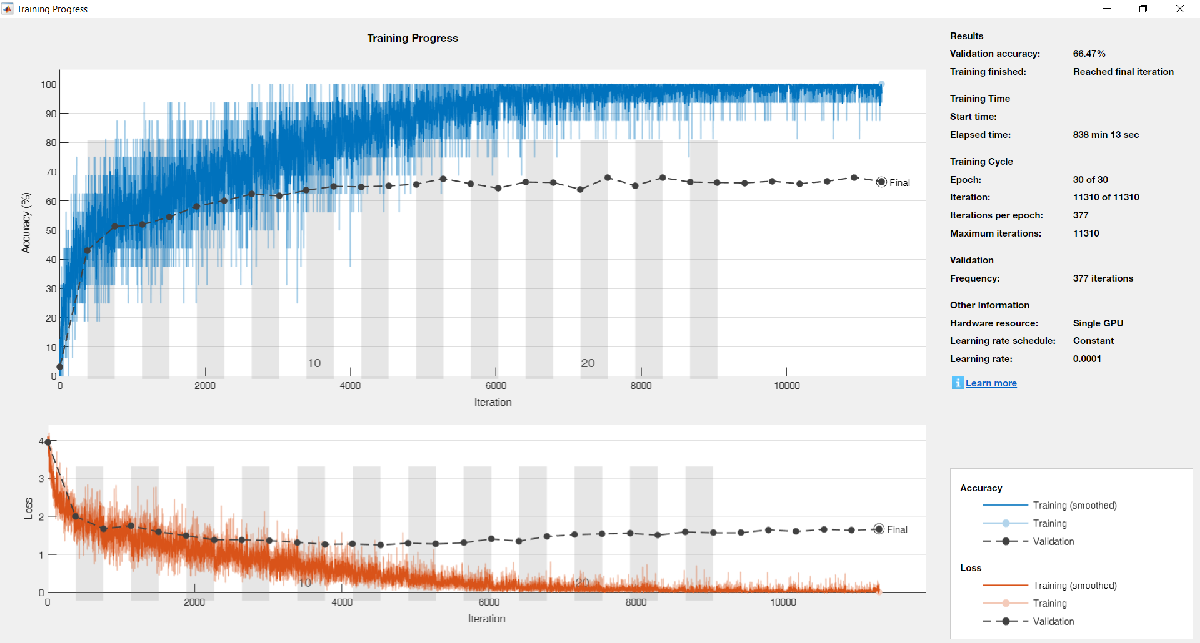

### Test LSTM Network

Calculate the classification accuracy of the network on the test set.. Use the same mini-batch size as for the training options.

% Classify the validation set
YPred = classify(netLSTM,sequencesTest,'MiniBatchSize',miniBatchSize);
% Evaluate the accuracy on the test set
accuracy = mean(YPred == labelsTest)

## References

[1] H. Kuehne, H. Jhuang, E. Garrote, T. Poggio, and T. Serre. HMDB: A Large Video Database for Human Motion Recognition. ICCV, 2011.

## Further Practice

- As you can see the test performance are low since the network parameters are not optimized and the network tend to overfitting. Try to change the parameters to improve the performance.

## Further readings

- [Long Short-Term Memory Networks](https://it.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html)

- [Sequence Classification Using Deep Learning](https://it.mathworks.com/help/deeplearning/ug/classify-sequence-data-using-lstm-networks.html)

- [Classify Videos Using Deep Learning](https://it.mathworks.com/help/deeplearning/ug/classify-videos-using-deep-learning.html)

## Helper Functions

The `readVideo` function reads the video in `filename` and returns an `H`-by-`W`-by-`C-`by-`S` array, where `H`, `W`, `C`, and `S` are the height, width, number of channels, and number of frames of the video, respectively.

function video = readVideo(filename)

vr = VideoReader(filename);
H = vr.Height;
W = vr.Width;
C = 3;

% Preallocate video array
numFrames = floor(vr.Duration * vr.FrameRate);
video = zeros(H,W,C,numFrames);

% Read frames
i = 0;
while hasFrame(vr)
    i = i + 1;
    video(:,:,:,i) = readFrame(vr);
end

% Remove unallocated frames
if size(video,4) > i
    video(:,:,:,i+1:end) = [];
end

end

The `centerCrop` function crops the longest edges of a video and resizes it have size `inputSize`.

function videoResized = centerCrop(video,inputSize)

sz = size(video);

if sz(1) < sz(2)
    % Video is landscape
    idx = floor((sz(2) - sz(1))/2);
    video(:,1:(idx-1),:,:) = [];
    video(:,(sz(1)+1):end,:,:) = [];
    
elseif sz(2) < sz(1)
    % Video is portrait
    idx = floor((sz(1) - sz(2))/2);
    video(1:(idx-1),:,:,:) = [];
    video((sz(2)+1):end,:,:,:) = [];
end

videoResized = imresize(video,inputSize(1:2));

end